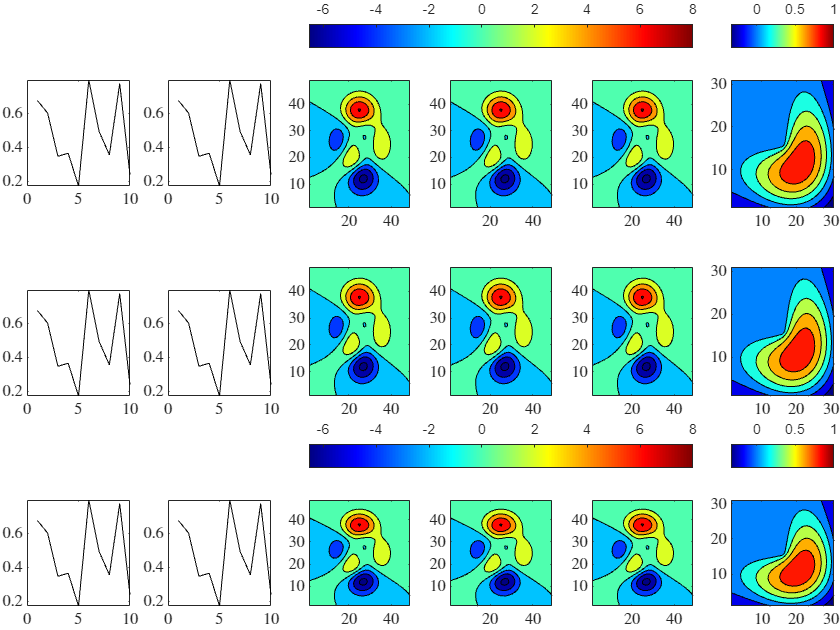

% Create randomize data---------------------------------------------------
dnum = 10;
p = rand([1,dnum]); % plots
pS_l1 = repmat(rand([dnum,dnum]),1,1,6); % surface/contour plots
pS_l2 = repmat(rand([dnum,dnum]),1,1,2); 
pS_l3 = repmat(rand([dnum,dnum]),1,1,3);
pS_l4 = rand([dnum,dnum]);


% Create the parent tiled layout chart------------------------------------
layoutP = tiledlayout(3,6,'TileSpacing','tight','Padding','tight');

% Create the children tiled layout charts
layoutC1 = tiledlayout(layoutP,2,3); % tile layout child 1
layoutC1.Layout.Tile = 3; layoutC1.Layout.TileSpan = [2 3];
layoutC2 = tiledlayout(layoutP,2,1); % tile layout child 2
layoutC2.Layout.Tile = 6; layoutC2.Layout.TileSpan = [2 1];
layoutC3 = tiledlayout(layoutP,1,3); % tile layout child 3
layoutC3.Layout.Tile = 15; layoutC3.Layout.TileSpan = [1 3];
layoutC4 = tiledlayout(layoutP,1,1); % tile layout child 4
layoutC4.Layout.Tile = 18; layoutC4.Layout.TileSpan = [1 1];

% Plot--------------------------------------------------------------------
figure()

% Parent plots
nexttile(layoutP,1)
plot(p,'k-');
nexttile(layoutP,2)
plot(p,'k-');
nexttile(layoutP,7)
plot(p,'k-');
nexttile(layoutP,8)
plot(p,'k-');
nexttile(layoutP,13)
plot(p,'k-');
nexttile(layoutP,14)
plot(p,'k-');

% Child 1 plots
axC1 = cell(1,6);
for i = 1:6 % iterate
    axC1{i} = nexttile(layoutC1,i);
    contourf(peaks); colormap(axC1{i},'jet');
    if i == 2 % attach colorbar and move it to c1 north
        cbC1 = colorbar(axC1{i});
        cbC1.Layout.Tile = 'North';
%         cbC1_H = cbC1.Position(4)*0.5; % new height
%         cbC1.Position(4) = cbC1_H;
%         cbC1.Position(2) = cbC1.Position(2) + 0.5*cbC1_H; % adjust the y-position
    end
end

% Child 2 plots
axC2 = cell(1,2);
for i = 1:2
    axC2{i} = nexttile(layoutC2,i);
    contourf(membrane); colormap(axC2{i},'jet');
    if i == 1
        cbC2 = colorbar(axC2{i});
        cbC2.Layout.Tile = 'North';
%         cbC2_H = cbC2.Position(4)*0.5;
%         cbC2.Position(4) = cbC1_H;
%         cbC2.Position(2) = cbC2.Position(2) + 0.5*cbC2_H;
    end
end

% Child 3 plots
axC3 = cell(1,3);
for i = 1:3
    axC3{i} = nexttile(layoutC3,i);
    contourf(peaks); colormap(axC3{i},'jet');
    if i == 2
        cbC3 = colorbar(axC3{i});
        cbC3.Layout.Tile = 'North';
%         cbC3_H = cbC3.Position(4)*0.5;
%         cbC3.Position(4) = cbC3_H;
%         cbC3.Position(2) = cbC3.Position(2) + 0.5*cbC3_H;
    end
end

% Child 4 plots
axC4 = nexttile(layoutC4,1);
contourf(membrane); colormap(axC4,'jet');
cbC4 = colorbar(axC4);
cbC4.Layout.Tile = 'North';

% cbC4_H = cbC4.Position(4)*0.5;
% cbC4.Position(4) = cbC4_H;
% cbC4.Position(2) = cbC4.Position(2) + 0.5*cbC4_H;